# Pose and end effector positioning

clear; clc

T1 = SE2(1,2, 30*pi/180) % Creates a homogenous transformation consisting x, y and theta

 

T1 = 
    0.8660   -0.5000         1
    0.5000    0.8660         2
         0         0         1


% Create axis
axis([0 5 0 5]) % Axis with limits 0 to 5
%trplot2(T1, 'frame', '1', 'color', 'b')

T2 = SE2(2, 1, 0)

 

T2 = 
         1         0         2
         0         1         1
         0         0         1


hold on
%trplot2(T2, 'frame', '2', 'color', 'r');

T3 = T1*T2

 

T3 = 
    0.8660   -0.5000     2.232
    0.5000    0.8660     3.866
         0         0         1


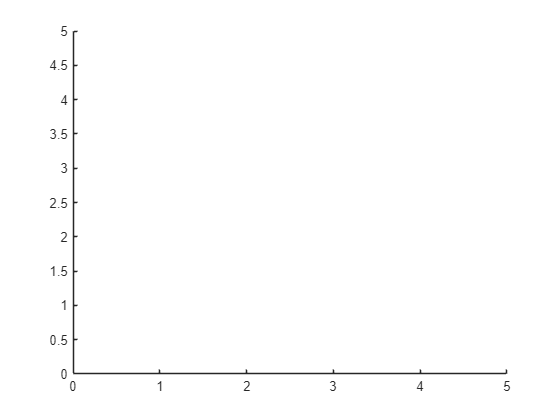

%trplot2(T3, 'frame', '3', 'color', 'g');

T4 = T2*T1;
%trplot2(T4, 'frame', '4', 'color', 'c');

P = [3 ; 2 ];
%plot_point(P, '*')

xlim([0 5])
ylim([0 5])
zlim([0 5])

% To get the coordinate of a point relative to myself
% Compute inverse of my position relative to world coordinate
% Then multiply by the position of the point relative to world coordinate
P1 = inv(T1.T) * [P; 1];
% The same can be expressed using the toolbox as:
h2e( inv(T1.T) * e2h(P));
% OR:
homtrans( inv(T1.T), P);